clear all, close all, clc

## HW04-3

Here,

A = 8.5e18;         % activity; #/s
N = 1;              % initial value

We know, $A\left(t\right)=\lambda \;N\left(t\right)$;

and,$N=A\;t$; when the activity is constant over time-period t

lam = A/N;          % decay const.; 1/s
t = 60^2*24*365;    % time; s/y
N_y = A*t           % no. of C-14 in y

N_y = 2.6806e+26

We know, mass of C-14 produced is-


$$m=M\frac{N_y }{N_A }$$


M = 14e-3;          % molar mass of C-14; kg/mol
NA = 6.023e23;      % Avogadro's number; #/mol
m = M *N_y/NA       % mass of C-14 per year; kg/y

m = 6.2308

(Ans)

## **HW04-4**

Fromt he following table, we have-

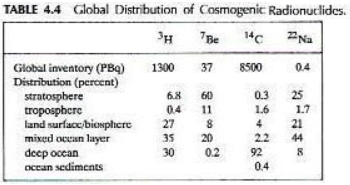

A = 0.4e15;         % global inventory of 22-Na; Bq

We know, 21% of it goes to biosphere. So-

A = A *0.21;        % Na-22 activity in bioshphere; Bq

We know, the half life of 22-Na = 2.6 year

T_h = 2.6*60^2*24*365;      % half life; s
lam = log(2)/T_h            % decay const.; s^-1

lam = 8.4537e-09

As we know, $A=\lambda \;N$

N = A/lam               % no. of 22-Na atoms

N = 9.9365e+21

Now, we know, $m=M\frac{N_y }{N_A }$

M = 22e-3;              % molar mass of Na-22; kg/mol
NA = 6.023e23;          % Avogadro's number; #/mol
m = M *N/NA             % equilibrium global mass of Na-22; kg

m = 3.6295e-04

m = m*1e3               % ; g

m = 0.3629

(Ans)

## HW04-8

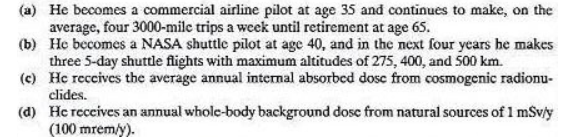

Here. we get from the book, the table-

### **(a) Doses due to terrestrial flight**

Lf = 65;                % Lifespan (assuming); y
y2 = 65;                % retirement age; y
y1 = 35;                % employing age; y
y_cr = y2 - y1          % career span; y 

y_cr = 30


n_w = 52.2;             % average no. of weeks in  a year
w_cr = y_cr *n_w        % career span in weeks

w_cr = 1566

Assuming the following things-

H_a = 8;            % altitude of flight; km
v_f = 600;          % avg. speed of flight; km/h
v_f = v_f*0.62      % mi/h

v_f = 372


n_tr = 4;           % no. of trips in a week
mi_wk = n_tr*3000   % milage travelled per week; mi

mi_wk = 12000

So, we can find

hr_wk = mi_wk/v_f       % no. of hours travelled in a week; hr/wk

hr_wk = 32.2581

hr_cr = hr_wk *w_cr     % no. of hours travelled in career

hr_cr = 5.0516e+04

Now, let's look at the following figure from the book-

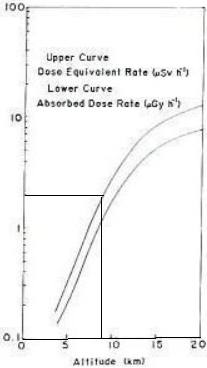 

We can say, for an altitude of 8 km of flight of commercial subsonic aviations, the hourly dose is 1.35 uSv/h. So we have-

Dr_av = 1.35e-3;          % aviational dose rate; mSv/h
D_av = Dr_av *hr_cr       % total absorbed dose for aviation career; mSv

D_av = 68.1968

### **(b) Doses due to space-flight**

For this, let's consider the following graph-

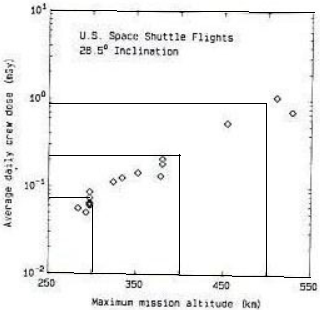

Given, the altitudes are: 27, 400, and 500 km respectively. We can approximate-

Dr_s1 = 0.08;               % dose rate, space travel, alt. 275 km; mGy/d
Dr_s2 = 0.2;                % @ 400 km; mGy/d
Dr_s3 = 1;                  % @ 500 km; mGy/d

n_d = 5;                % no. of days
D_sp = (Dr_s1 + Dr_s2 + Dr_s3) *n_d      % mGy

D_sp = 6.4000

Taking 1.0 for whole body 

Wf = 1.0;                   % whole body weighting factor
D_sp = D_sp * Wf            % effective dose; mSv

D_sp = 6.4000

### **(c) Doses from cosmogenic radionuclide absorption**

Let's tabulate the weight fraction given in the book

wf_st = 0.23;               % weighting fraction, soft tissue
wf_g = 0.089;               % gonad        
wf_rm = 0.41;               % red marrow
wf_sk = 0.25;               % skeleton

wf_li = 0.12;               % colon/large intestine
wf_wb = 1.0;                % whole body

Now, let's find the doses for various cosmogenic radionuclides

**    from 3-H**

Dr_T_wb = 0.01e-3;           % dose from Tritium, whole body; mGy/y
Dr_T_wb = Dr_T_wb *wf_wb;    % mSv/y

Then, total dose absorbed in the whole body

D_T_T = Dr_T_wb *Lf        % total dose from H-3 in lifetime; mSv

D_T_T = 6.5000e-04

**    from 14-C**

Dr_C_st = 13e-3;            % dose from 14-C, soft tissue; mGy/y
Dr_C_st = Dr_C_st *wf_st    % mSv/y

Dr_C_st = 0.0030

Dr_C_g = 5e-3;              % dose from 14-C, gonad; mGy/y
Dr_C_g = Dr_C_g *wf_g       % mSv/y

Dr_C_g = 4.4500e-04

Dr_C_rm = 23e-3;            % dose from 14-C, red marrow; mGy/y
Dr_C_rm = Dr_C_rm *wf_rm    % mSv/y

Dr_C_rm = 0.0094

Dr_C_sk = 14e-3;            % dose from 14-C, skeleton; mGy/y
Dr_C_sk = Dr_C_sk *wf_sk    % mSv/y

Dr_C_sk = 0.0035

So, total dose absorbed from 14-C

Dr_C_T = Dr_C_st + Dr_C_g + Dr_C_rm + Dr_C_sk   % mSv/y

Dr_C_T = 0.0164

D_C_T = Dr_C_T * Lf                             % total dose from C-14 in lifetime; mSv

D_C_T = 1.0637

**    from 7-Be**

Dr_Be_li = 12e-3;               % dose from 7-Be, colon; mGy/y
Dr_Be_li = Dr_Be_li *wf_li      % mSv/y

Dr_Be_li = 0.0014

Dr_Be_rm = 1.2e-3;              % dose from 7-Be, red marrow; mGy/y
Dr_Be_rm = Dr_Be_rm *wf_rm      % mSv/y

Dr_Be_rm = 4.9200e-04

Dr_Be_g = 5.7e-3;               % dose from 7-Be, gonad; mGy/y
Dr_Be_g = Dr_Be_g *wf_g         % mSv/y

Dr_Be_g = 5.0730e-04

So, total dose absorbed from 7-Be

Dr_Be_T = Dr_Be_li + Dr_Be_rm + Dr_Be_g     % mSv/y

Dr_Be_T = 0.0024

D_Be_T = Dr_Be_T * Lf                       % total dose from Be-7 in lifetime; mSv

D_Be_T = 0.1586

**   from 22-Na**

Dr_Na_st = 0.15e-3;              % dose from 22-Na, soft tissue; mGy/y
Dr_Na_st = Dr_Na_st *wf_st       % mSv/y

Dr_Na_st = 3.4500e-05

Dr_Na_rm = 0.22e-3;              % dose from 22-Na, red marrow; mGy/y
Dr_Na_rm = Dr_Na_rm *wf_rm       % mSv/y

Dr_Na_rm = 9.0200e-05

Dr_Na_sk = 0.27e-3;              % dose from 22-Na, skeleton; mGy/y
Dr_Na_sk = Dr_Na_sk *wf_sk       % mSv/y

Dr_Na_sk = 6.7500e-05

So, total dose absorbed from 22-Na

Dr_Na_T = Dr_Na_st + Dr_Na_rm + Dr_Na_sk        % mSv/y

Dr_Na_T = 1.9220e-04

D_Na_T = Dr_Be_T * Lf                           % total dose from Na-22 in lifetime; mSv

D_Na_T = 0.1586

     **Total Cosmogenic Radionuclide Dose**

D_Cs = D_T_T+ D_C_T + D_Be_T +  D_Na_T          % total cosmogenic dose; mSv

D_Cs = 1.3815

### **(d) Dose from background**

Dr_b = 1;           % Annual whole body background dose-rate; mSv/y
D_b = Dr_b*Lf       % lifetime background dose; mSv

D_b = 65

So, from all the conditions from a to d, we find- the total lifetime absorbed dose

D_T = D_b + D_Cs + D_av + D_sp              % total lifetime dose; mSv

D_T = 140.9783

### Finding Cancer Risk

Now, let's find the cancer risk. Let's do it for leukemia. Here, taking the dose for whole body

D = D_T /wf_wb;             % received dose, mGy
D = D*1e-3;                 % Gy
a0 = 35;                    % assuming 'big-time' exposures comes after starting occupation

Let's think about cancer-probability at the end of his career. Then-

a = 65;             % age of contraction
t = a - a0;        % latency period

We know the relative risk for leukemia, frob textbook eq(3.47) is-

Here, we have, 

g = 1.638;
R_L = (0.243*D + 0.271 *D^2).*exp(g)

R_L = 0.2040

So, we see, the excess cancer (leukemia) risk would be-

Ex_L = R_L *100           % percent(%)

Ex_L = 20.3962

(Ans)

This way, the increased probability could be found for other form of cancers. 

## HW04-9

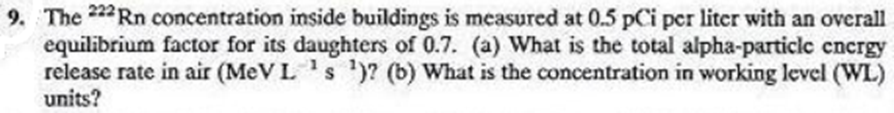

Given,

C = 0.5e-12;            % activity conc.; Ci/L
C = C*37e9;             % Bq/L; 1/L.s
F = 0.7;                % overall equilibrium factor
C_EE = F *C             % equilibrium equivalent conc.; 1/L.s

C_EE = 0.0129

C_EEw = C_EE/1e-3       % activity conc. for WL; 1/s.m^3

C_EEw = 12.9500

**(a) Energy Release Rate**

Now, for Rn-222 to be in equilibrium with its daughters, it goes like-

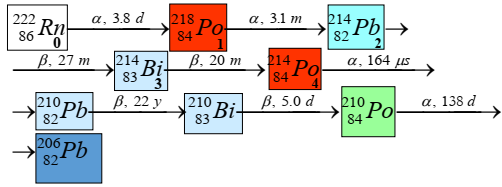


$$E=C\left(E_1 +E_4 \right)$$


Here we know,

E1 = 6.003;         % MeV
E4 = 7.687;         % MeV

Then, the energy release rate

E_r = C_EE * (E1 + E4)/2          % MeV/L.s

E_r = 0.0886

(Ans)

**(b) WL concentration**

Here, total PAEC when at equilibrium is-

Now, let's find the decay constants

t_h1 = 3.1*60;          % half-life; s
t_h2 = 27*60;           % s
t_h3 = 20*60;           % s
t_h4 = 164e-6;          % s

lam1 = log(2)/t_h1      % decay const.; s^-1

lam1 = 0.0037

lam2 = log(2)/t_h2      % s^-1

lam2 = 4.2787e-04

lam3 = log(2)/t_h3      % s^-1

lam3 = 5.7762e-04

lam4 = log(2)/t_h4      % s^-1

lam4 = 4.2265e+03

So, total a-particle energy release rate would be

  lamE = 1/(1/lam2 + 1/lam3 + 1/lam4);      % defining an equivalent lambda
E_Tc = C_EEw *(E1/lam1 + E4/lamE)           % MeV/m^3.s

E_Tc = 4.2586e+05

Now, let's convert it to WL

  MeV_WL = 1.3e8;             % MeV/m^3 @ WL
E_Tc = E_Tc /MeV_WL

E_Tc = 0.0033

(Ans)

## HW04-12

Given

C = 0.1e-6;         % activity conc.; Ci/m^-3
C = C*37e9          % Bq/m^-3; 1/s.m^-3

C = 3700

Here, the thoron decay chain is-

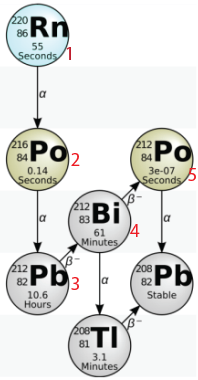

Now, from the nuclide chart, we get the following

E1 = 6.288;             % of Rn-220; MeV
E2 = 6.779              % of Po-216; MeV

E2 = 6.7790

E5 = 11.65;             % of Po-212; MeV

Now, let's find the decay constants

t_h1 = 55;              % half-life, s
t_h2 = 0.14;            % s
t_h3 = 10.6*60^2;       % s
t_h4 = 61*60;           % s
t_h5 = 3e-7;            % s

lam1 = log(2)/t_h1      % decay const. 1/s

lam1 = 0.0126

lam2 = log(2)/t_h2      % 1/s

lam2 = 4.9511

lam3 = log(2)/t_h3      % 1/s

lam3 = 1.8164e-05

lam4 = log(2)/t_h4      % 1/s

lam4 = 1.8938e-04

lam5 = log(2)/t_h5      % 1/s

lam5 = 2.3105e+06

So, from decay cahin, letting it in equilibrium, we can say-

${E^{\textrm{eq}} }_{c,T} =C\left(\frac{E_1 }{\lambda {\;}_1 }+\frac{E_2 }{\lambda {\;}_2 }+E_5 \left(\frac{1}{\lambda_3 }+\frac{1}{\lambda_4 }+\frac{1}{\lambda_5 }\right)\right)$    ${E^{\textrm{eq}} }_{c,T} =$ a-energy concentration, total 

  lamE = 1/(1/lam3 + 1/lam4 + 1/lam5)   % defining an equivalent lambda

lamE = 1.6575e-05

E_ct = C*(E1/lam1 + E2/lam2 + E5/lamE)  % MeV/m^3

E_ct = 2.6025e+09

To convert it to the WL, we get

E_ct = E_ct/1.38e8                      % WL

E_ct = 18.8589

(Ans)

### Method 2

Given,

C = 0.1e-6;         % activity conc.; Ci/m^-3
C = C*37e9          % Bq/m^-3; 1/s.m^-3

C = 3700

Now, from book, p188, we get, 1 WL is equivalent to 275 Bq/m^3. So, 

  Bqm3_WL = 275;        % WL /Bq/m^3
C_WL = C/Bqm3_WL        % WL

C_WL = 13.4545

(Ans)

## HW04-14

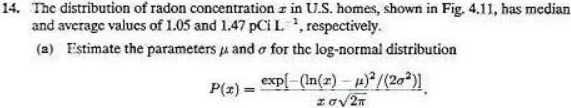

### (a)

Given,

x_m = 1.05;         % median; pCi.L^-1
x_a = 1.47;         % average

mu = log(x_m)       % pCi^.L^-1

mu = 0.0488

(Ans)

Now, we know, $x_{\mathrm{av}} =\exp \left(\mu +\frac{{\;\sigma }^2 }{2}\right)$

So, from this we have-

sg = sqrt(2*(log(x_a) - mu))        % pCi^.L^-1

sg = 0.8203

(Ans)

### (b)

Now, we know, the cumilitive probability density for x is-

and, error function is: $\textrm{erf}\left(x\right)=\frac{2}{\sqrt{\pi \;\;}}{\int \;}_0^x \;\exp \left(t^{-2} \right)\;\textrm{dt}$

So, the cumilitive probability of homes having conc. of 2 pCi/L would be-

x = 2;
  fr = (log(x) - mu) /(2^0.5 *sg);  % defining fraction
y  = 0.5*(1 + erf (fr))

y = 0.7839

So, fraction exceeding that amount would be-

y_b = 1 - y

y_b = 0.2161

(Ans)

Now, figure 4.11 shows-

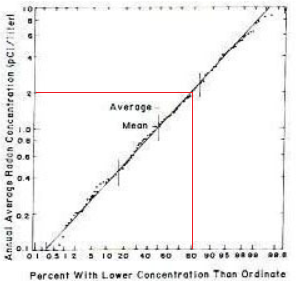

So, we can see from the above figure that almost 80%  of the home stays below the 2 pCi/L^-1 limit and 20% is above it, which quite accurately matches with the calculation of fraction(0.784, 0.216); percentage-wise which his 78.4% and 21.6%. 